# Homework 5  - Farshad Bolouri - R11630884

### Problem 1)

Explain why it is impossible to realize a discrete-time ideal lowpass filter.

*We cannot implement the ideal lowpass filter in practice because its impulse response is infinitely long in time. It is also noncausal; it cannot be shifted to make it causal because the impulse response extends all the way to time . It is clear we will have to accept some sort of compromise in the design of any practical lowpass filter.*

*In summary:*

- ***It is infinitely Non-Causal***

- ***It is unstable***

- ***The system is not rational***

### Problem 2)

We want to design a linear-phase FIR low-pass filter that meets the following constraints:

- The filter should operate on discrete signals that were sampled at 16000 samples/second.

- Frequencies up to 4000 Hz should be maintained with a distortion no greater than 1 dB.

- Frequencies higher than 6000 Hz should be attenuated at least 40dB.

- We want to minimize the number of coefficients in the filter.

You want to compare the following design methods:

- Window method (justify the choice of your window) 

- iterative approximation method (i.e. Parks-McClellan) 

- least squares method

[toneramp, fs] = audioread("toneramp.wav");

#### Filtering using Kaiser Window - Window Method

*I am using the Kaiser window because after testing with other windows such as Hamming, Gaussian, Hann, Blackman, and several others, none of them would produce a filter that met our conditions while having a lower filter order than the one I designed with the Kaiser window.*

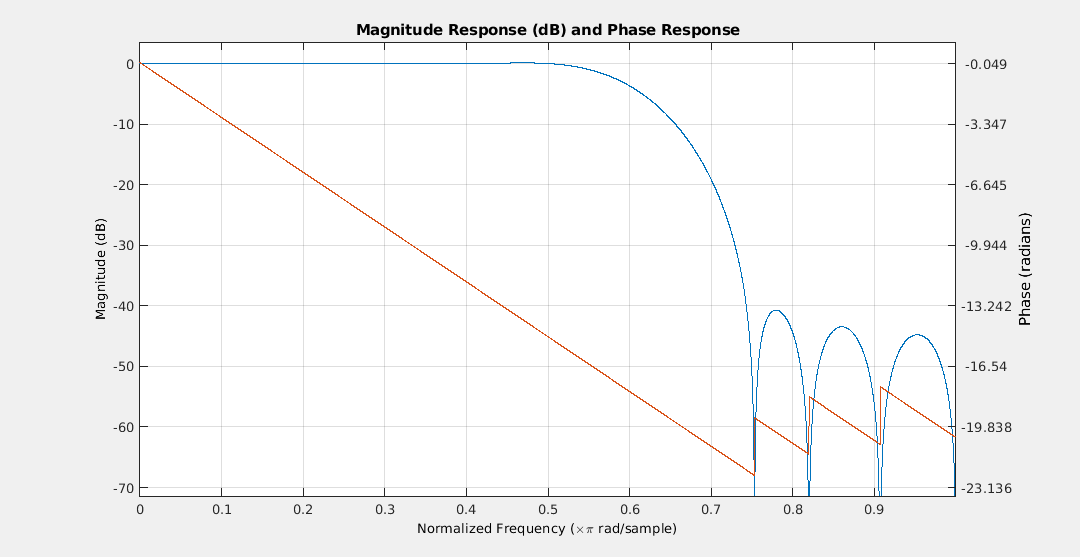

KFilter = Kaiser;
figure
freqz(KFilter)

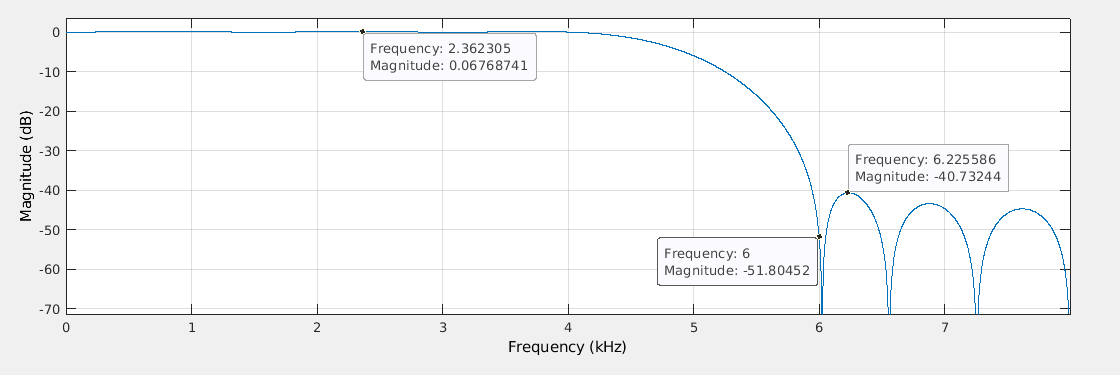

- *For frequencies up to 4000 Hz the highest distortion value is around 0.067 dB which is less than 1 dB. ✔*

- *Frequencies higher than 6000 Hz are all attenuated to above 40 dB. ✔ *

- *The filter was designed with minimum order conditions: Order = 19 ✔ *

***side note: ****MATLAB's filter designer would give an order 18 filter if you set FPass = 4000, Fstop = 6000, and Astop = 40 under minimum order conditions. However this filter doesn't exactly comply with the conditions of this problem. Here's the proof on the frequency response:*

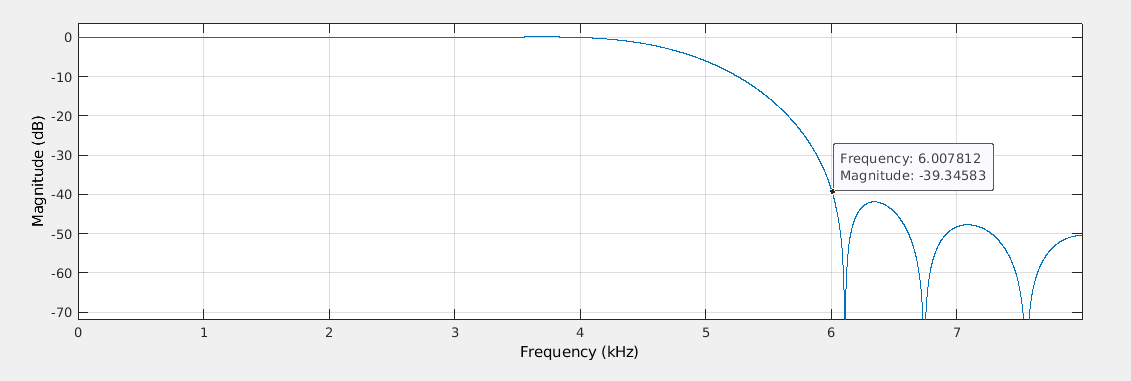

*As you can see on very small frequencies above 6KHz, it actualy doesn't attenuate our signal to exactly above 40dB.*

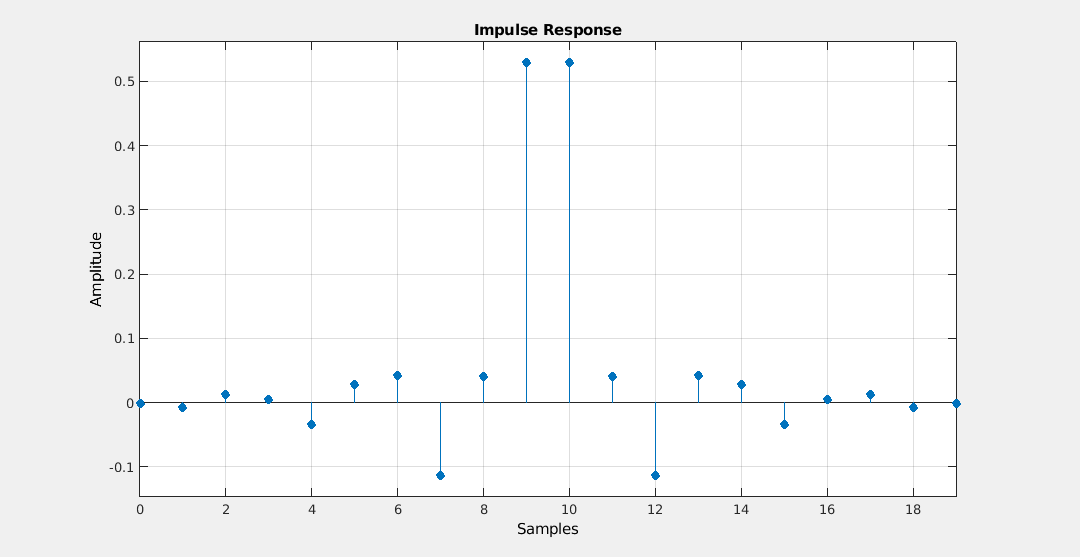

figure
impz(KFilter)

*The impulse response is a symmetric sinc function as it should be in FIR filters.*

*This is an Optimum Type II filter as the filter order is Odd and the symmetry of the coefficients are Even.*

*The impulse response has 20 taps on its symmetry which makes sense with respect to the definition of the Type II filters.*


$$\mathrm{Number}\;\mathrm{of}\;\mathrm{taps}=\mathrm{order}+1$$



$$20=19+1$$


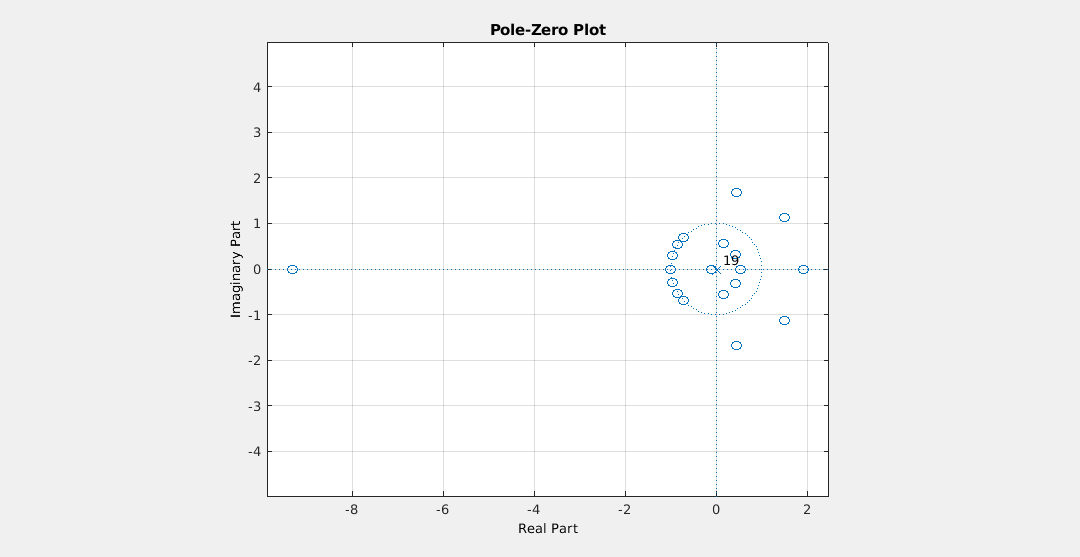

figure
zplane(KFilter)

You can see how the zeros are mirrored and conjugate pairs on the zplane. You can also see several zeros along the unit circle and reciprocal pairs which is a trait of the Kaiser window filters.

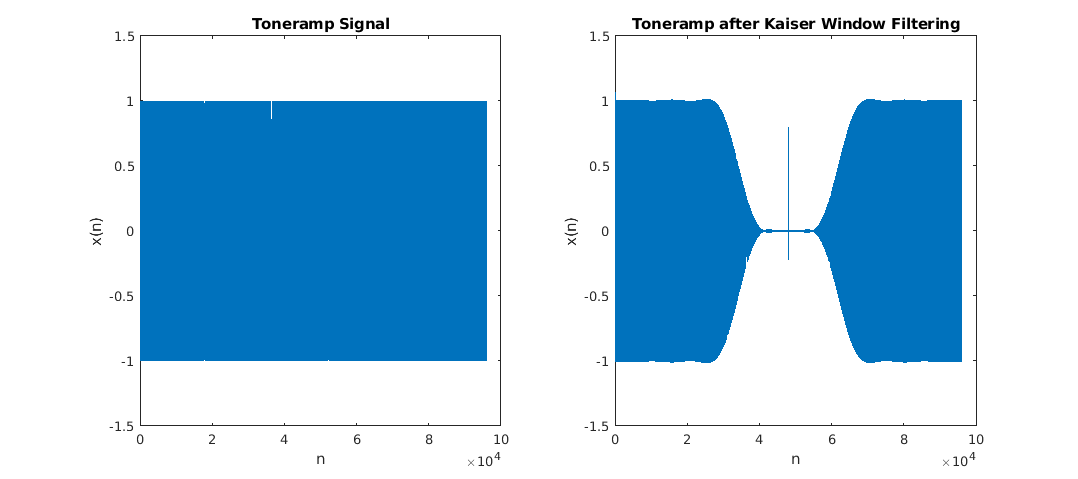

% Filtering the signal
toneramp_KFiltered = filter(KFilter, toneramp);

audiowrite('toneramp_KFiltered.wav', toneramp_KFiltered, fs);

h = figure;
subplot(121)
plot(toneramp)
title('Toneramp Signal')
xlabel('n')
ylabel('x(n)')
ylim([-1.5 1.50])

subplot(122)
plot(toneramp_KFiltered)
title('Toneramp after Kaiser Window Filtering')
xlabel('n')
ylabel('x(n)')
set(h,'Units','normalized','Position',[0 0 1 0.25]);

*After listening to the audio file, you can definitely tell that the high frequency component in the original audio is not there anymore and you barely can hear it.*

*Also, if you listen very carefully, you can hear the small ripple effect around the first and fourth second. You can also see the ripple in the plot! *

#### Equiripple Filter - Iterative Approximation method 

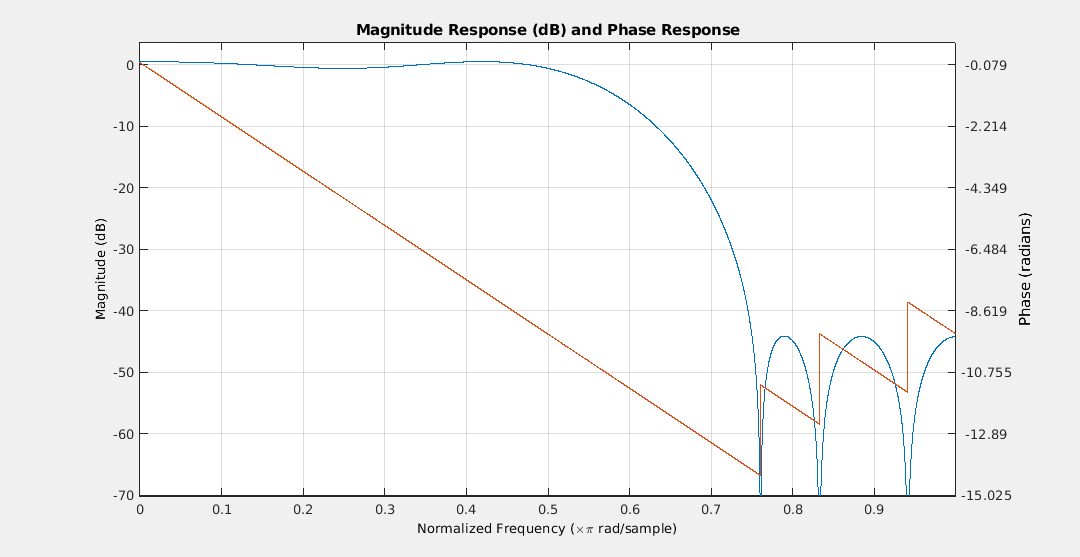

EqFilter = Equiripple;
figure
freqz(EqFilter)

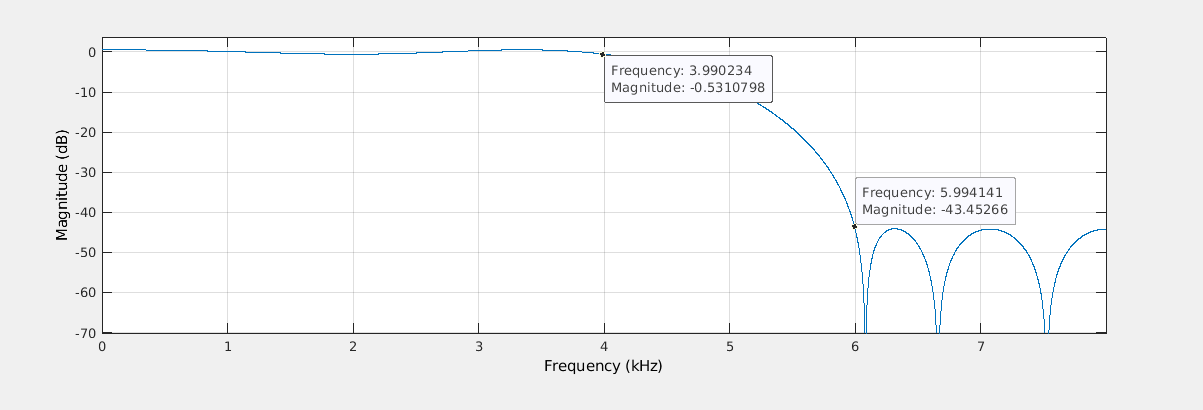

- *For frequencies up to 4000 Hz the highest distortion value is around 0.53 dB which is less than 1 dB. ✔*

- *Frequencies higher than 6000 Hz are all attenuated to above 43 dB which is greater than 40 dB. ✔ *

- *The filter was designed with minimum order conditions: Order = 12 ✔ *

***side note: ****MATLAB's filter designer would give an order 10 filter if you set FPass = 4000, Fstop = 6000, and Astop = 40 under minimum order conditions for Equiripple filter. However this filter doesn't exactly comply with the conditions of this problem. Here's the proof on the frequency response:*

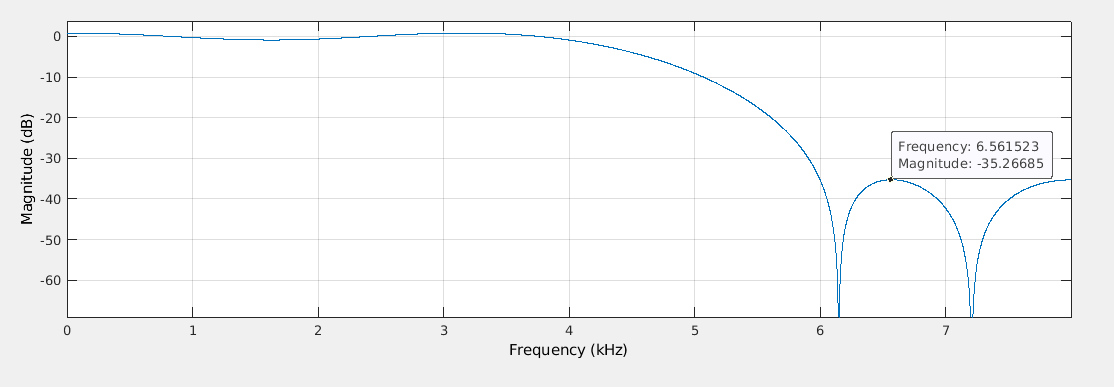

*As you can see on very small frequencies above 6KHz, it actualy doesn't attenuate our signal to exactly above 40dB.*

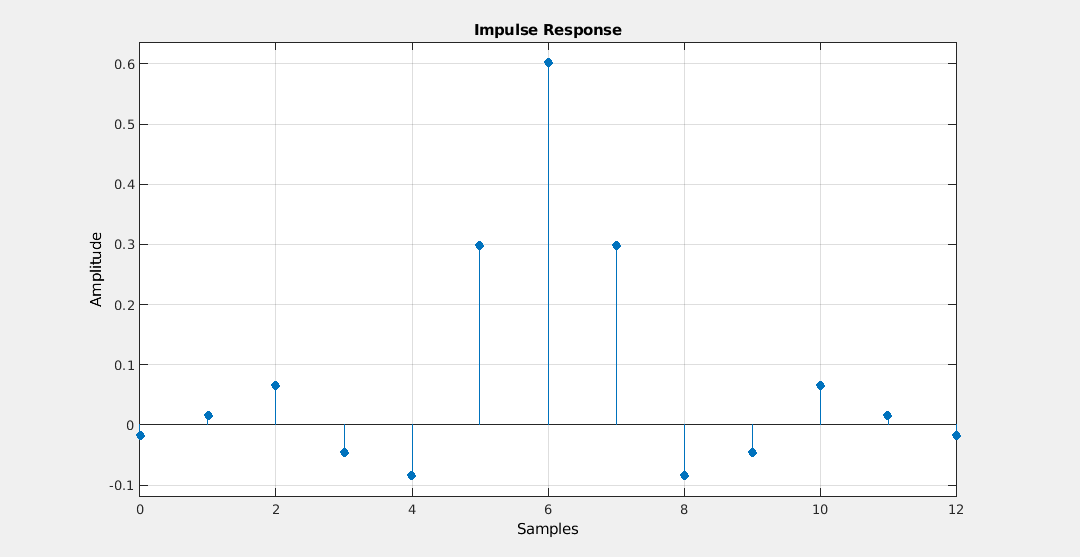

figure
impz(EqFilter)

*The impulse response is a symmetric sinc function as it should be in FIR filters.*

*This is an Optimum Type I filter as the filter order is Even and the symmetry of the coefficients are also Even.*

*The impulse response has 6 taps on each side of the middle tap which adds up to the order of our filter (12).*

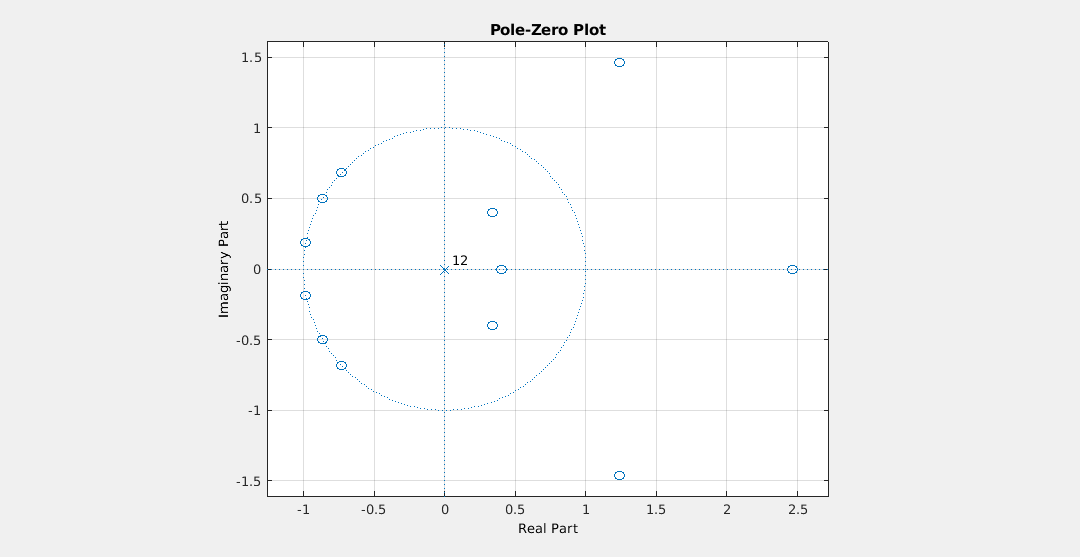

figure
zplane(EqFilter)

You can see how the zeros are mirrored and conjugate pairs on the zplane. You can also see several zeros along the unit circle and reciprocal pairs which is a trait of the Equiripple filters.

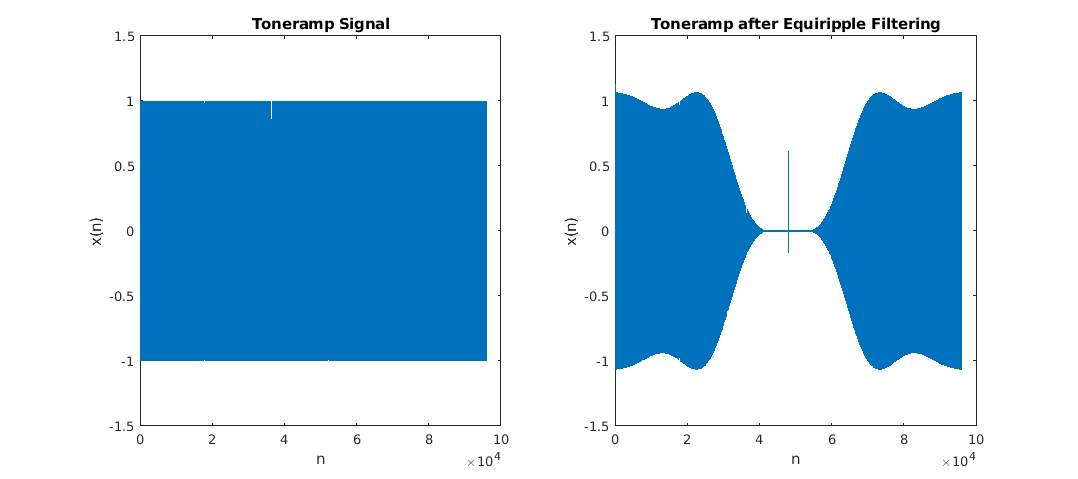

% Filtering the signal
toneramp_EqFiltered = filter(EqFilter, toneramp);

audiowrite('toneramp_EqFiltered.wav', toneramp_EqFiltered, fs);

h = figure;
subplot(121)
plot(toneramp)
title('Toneramp Signal')
xlabel('n')
ylabel('x(n)')
ylim([-1.5 1.50])

subplot(122)
plot(toneramp_EqFiltered)
title('Toneramp after Equiripple Filtering')
xlabel('n')
ylabel('x(n)')
set(h,'Units','normalized','Position',[0 0 1 0.25]);

*After listening to the audio file, you can definitely tell that the high frequency component in the original audio is not there anymore and you barely can hear it same as the Kaiser Window filtering.*

*However, if you listen carefully, you can hear multiple ripple effects This time. You can see how the ripples are more exagerated in this plot as well.*

#### Least Squares Filtering

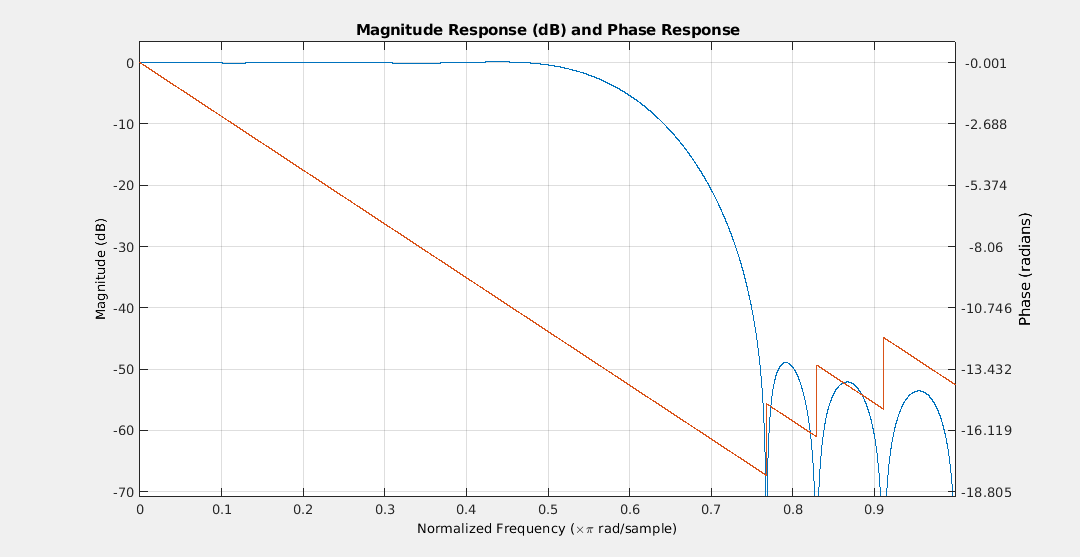

LsFilter = LeastSquares;
figure
freqz(LsFilter)

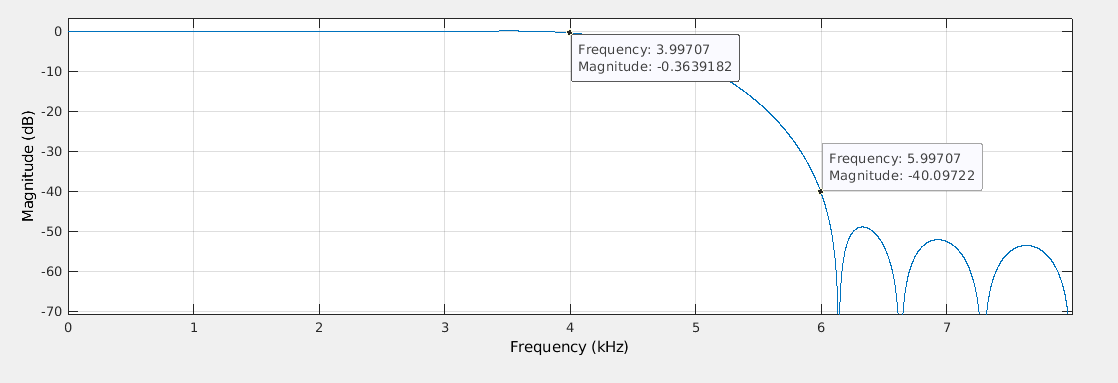

- *For frequencies up to 4000 Hz the highest distortion value is around 0.36 dB which is less than 1 dB. ✔*

- *Frequencies higher than 6000 Hz are all attenuated to above 40 dB. ✔ *

- *The filter was designed with minimum order conditions: Order = 15 ✔*

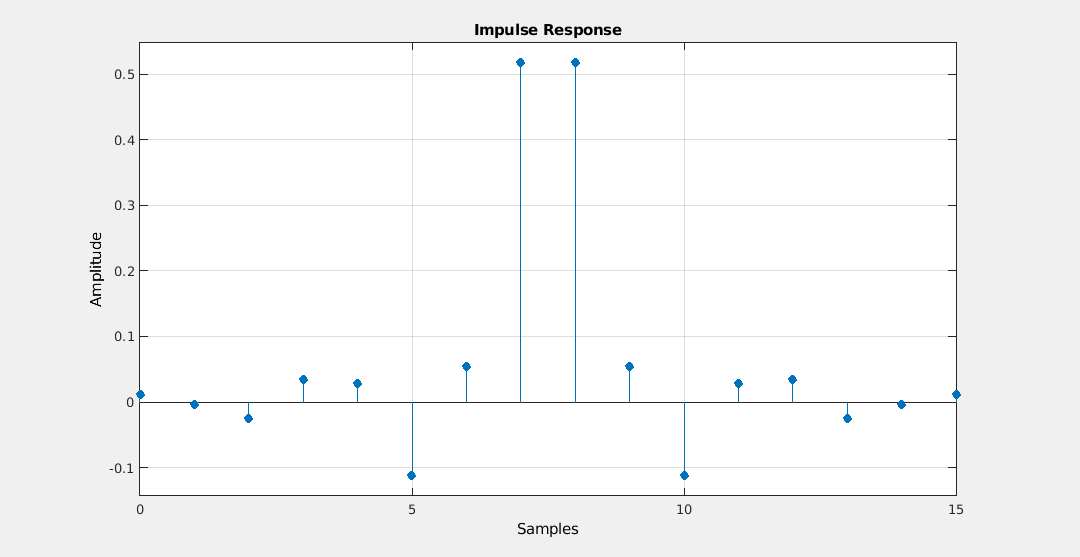

figure
impz(LsFilter)

*The impulse response is a symmetric sinc function as it should be in FIR filters.*

*This is an Optimum Type II filter as the filter order is Odd and the symmetry of the coefficients are Even.*

*The impulse response has 20 taps on its symmetry which makes sense with respect to the definition of the Type II filters.*


$$\textrm{Number}\;\textrm{of}\;\textrm{taps}=\textrm{order}+1$$



$$16=15+1$$


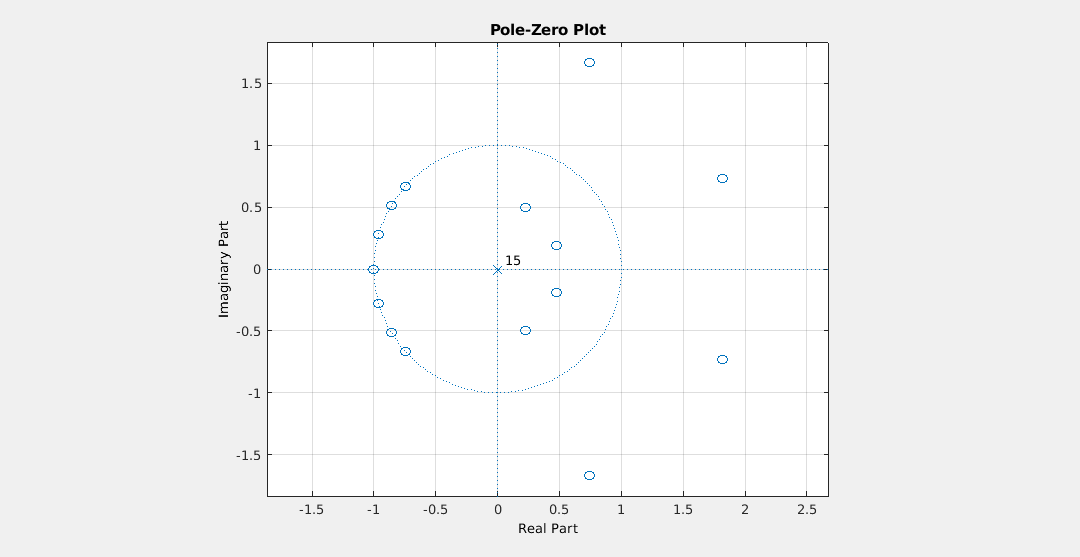

figure
zplane(LsFilter)

You can see how the zeros are mirrored and conjugate pairs on the zplane. You can also see several zeros along the unit circle which is a trait of the Equiripple filters.

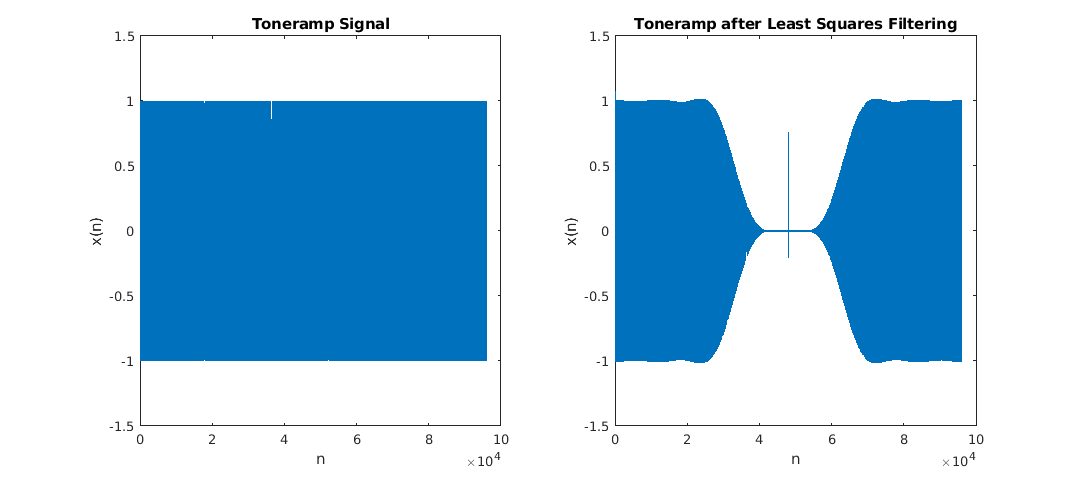

% Filtering the signal
toneramp_LsFiltered = filter(LsFilter, toneramp);

audiowrite('toneramp_LsFiltered.wav', toneramp_LsFiltered, fs);

h = figure;
subplot(121)
plot(toneramp)
title('Toneramp Signal')
xlabel('n')
ylabel('x(n)')
ylim([-1.5 1.50])

subplot(122)
plot(toneramp_LsFiltered)
title('Toneramp after Least Squares Filtering')
xlabel('n')
ylabel('x(n)')
set(h,'Units','normalized','Position',[0 0 1 0.25]);

*After listening to the audio file, again, you can tell that the high frequency component in the original audio is not there anymore and you barely can hear it.*

*The ripple effect is similar to the Kaiser Window filtering in this one.. You can also see the small rippling effect in the plot! *

Now Compare the filter designs:

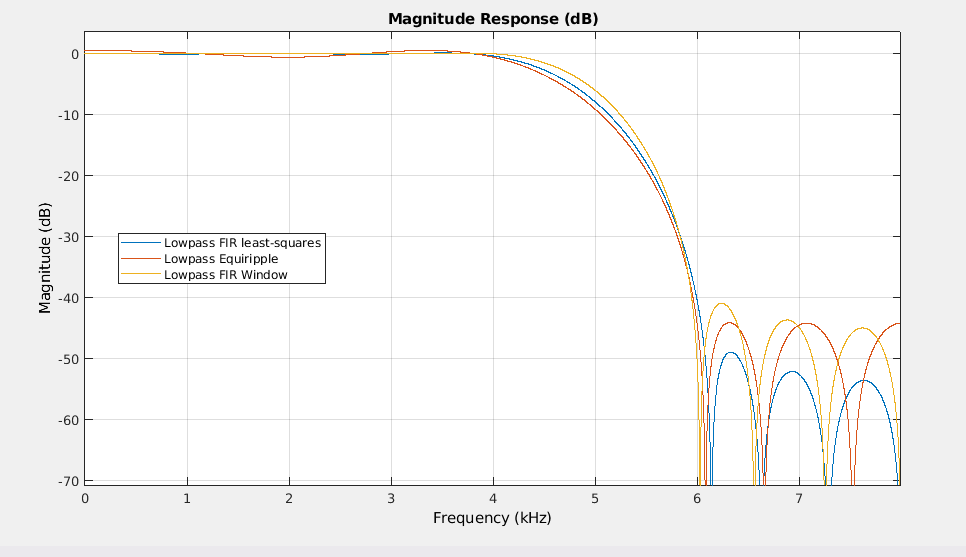

*The frequency responses look pretty similar as youcan see. The main differences are:*

- *You can see the more rippling effect (distortions) in the Equiripple filter with respect to the other two. (0 to 4 KHz range)*

- *You can see how the equiripple tend to have a more constant stopband attenuation while the other two seem to have a decreasing attenuation as the frequency increases.*

- *The kaiser window filter, has the widest passband between the three and the Equiripple has the narrowest.*

*As I explained about the filtered audios in the previous sections, I can say that the Kaiser window filter had the best (cleanest) output with respect to the problem's constraints. However, the Kaiser window filter has the highest order between the three which means more computation complexity. *

*The Equiripple filter had the least filter order therefore least complexity in terms of computation. However it gave us the worst filtered audio in terms of the quailty of the output. It had the most ripples (distortions) in the filtered signal.*

*The Least Sqaures filter, was in the middle int terms of filter order (15) and it also gave us a decent filtered signal which in terms of quailty was very close to the Kaiser one.*

*In terms of difficulty of the design process, I would say that all three had were almost the same. However the Equripple and Kaiser Window was slightly easier as they provided the "Minimum Order" option in the design process. But I still had to play with the magnitude specifications for all three.*

*In conclusion, I wouldn't say one of them was the best out of three as they all had their pros and cons. (As mentioned above).*

### Problem 3)

Design an IIR filter that meets the same constraints as in Problem 2. You may use any design method you choose.

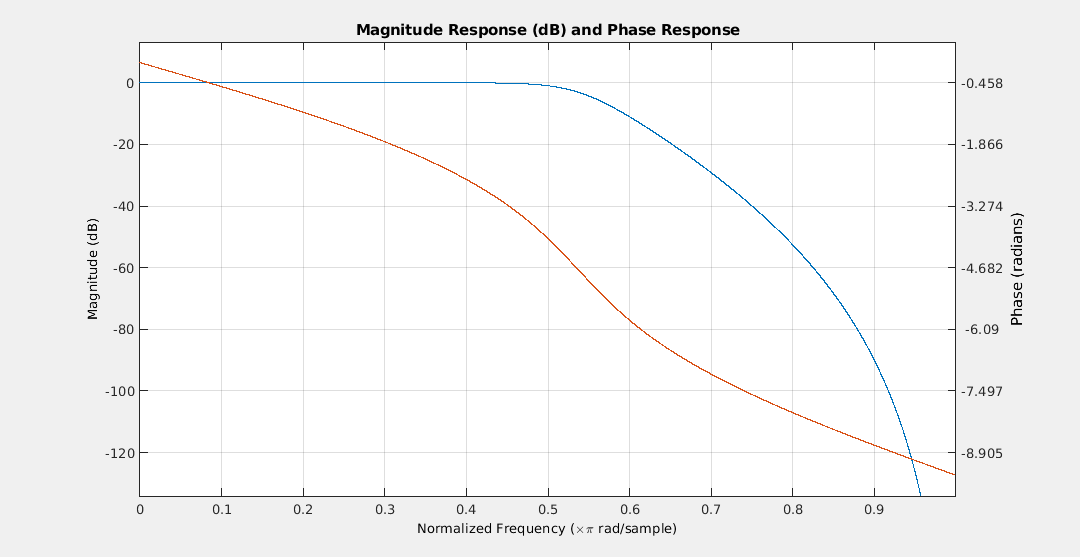

butterFilter = Butterworth;
figure
freqz(butterFilter)

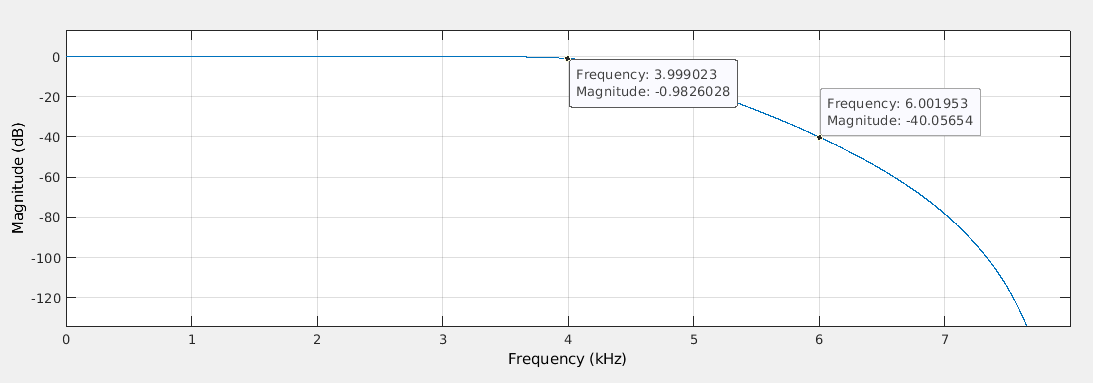

- *For frequencies up to 4000 Hz the highest distortion value is around 0.98 dB which is less than 1 dB. ✔*

- *Frequencies higher than 6000 Hz are all attenuated to above 40 dB. ✔ *

- *The filter was designed with minimum order conditions: Order = 6 ✔*

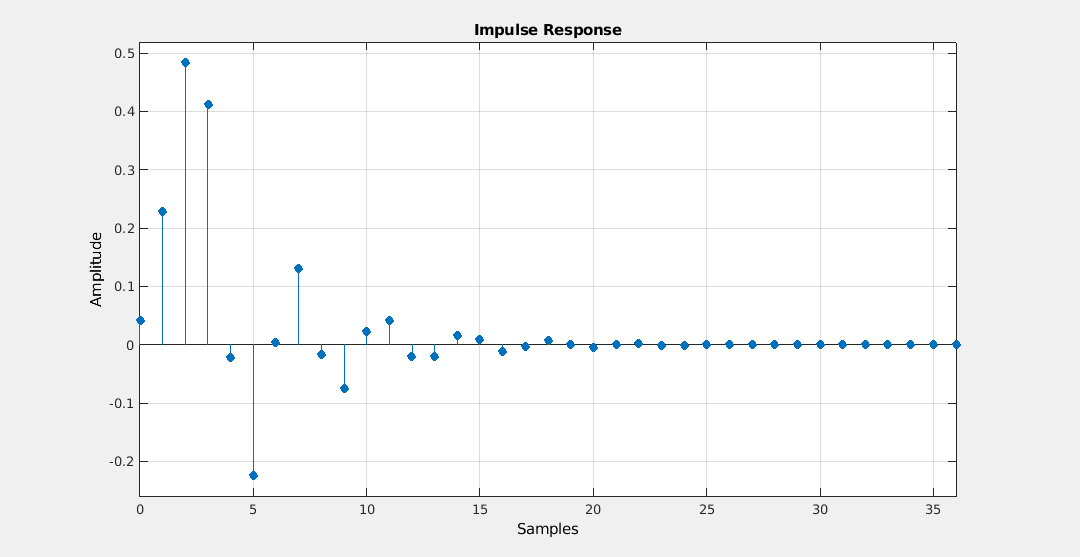

figure
impz(butterFilter)

*The impulse response is a sinc function but as you can see the function does not look symmetric!*

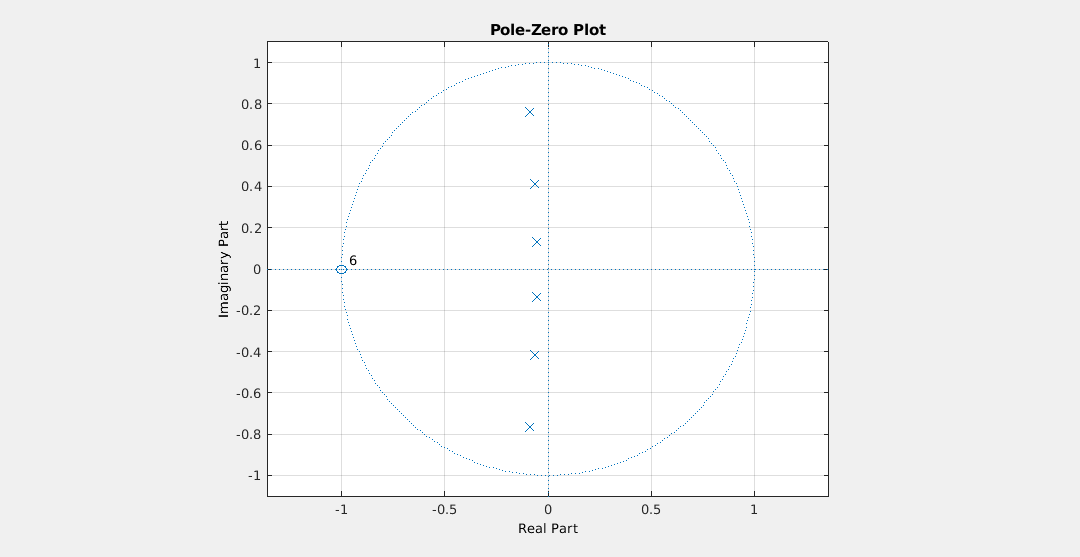

figure
zplane(butterFilter)

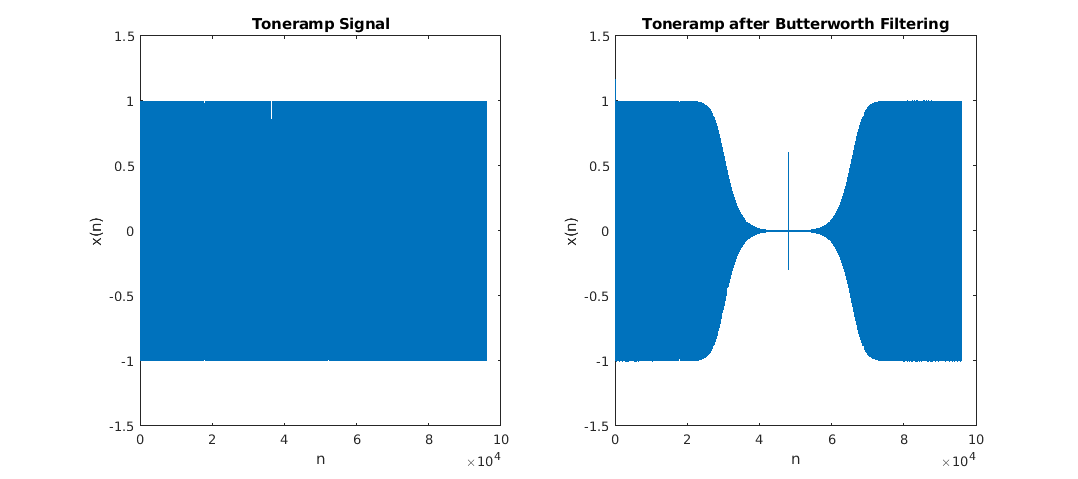

% Filtering the signal
toneramp_butterFiltered = filter(butterFilter, toneramp);

audiowrite('toneramp_butterFiltered.wav', toneramp_butterFiltered, fs);

h = figure;
subplot(121)
plot(toneramp)
title('Toneramp Signal')
xlabel('n')
ylabel('x(n)')
ylim([-1.5 1.50])

subplot(122)
plot(toneramp_butterFiltered)
title('Toneramp after Butterworth Filtering')
xlabel('n')
ylabel('x(n)')
set(h,'Units','normalized','Position',[0 0 1 0.25]);

*I tried with several IIR filters and I decided to go with the butterworth filter as it gave me the smoothest transition and best output while meeting the constraints and maintainig a small order.*

*The only other good filter that was comparable to butterworth was the Chebyshev Type II filter.*

*Here's a comparison between the two:*

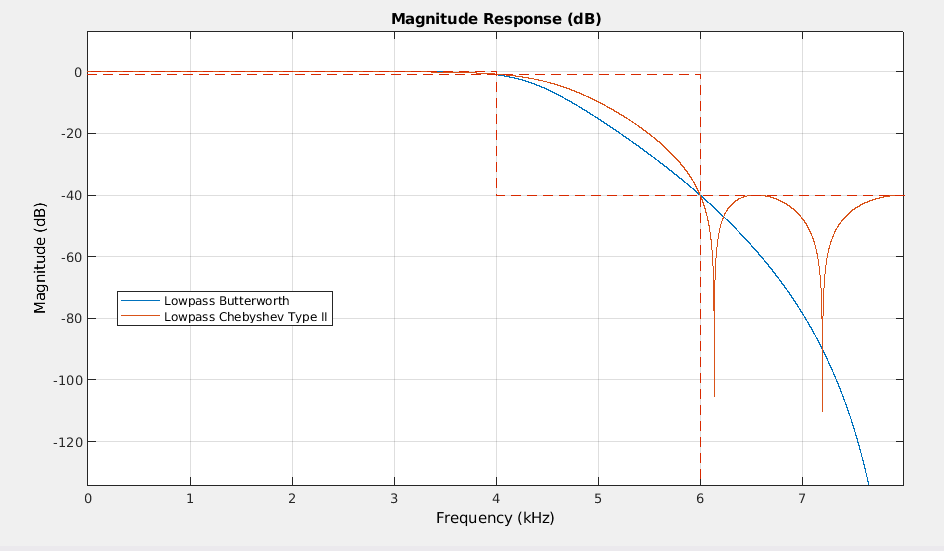

*As you can see, Chebyshev Type II has a wider passband. But the filter order is only 4 which is less than butterworth. *

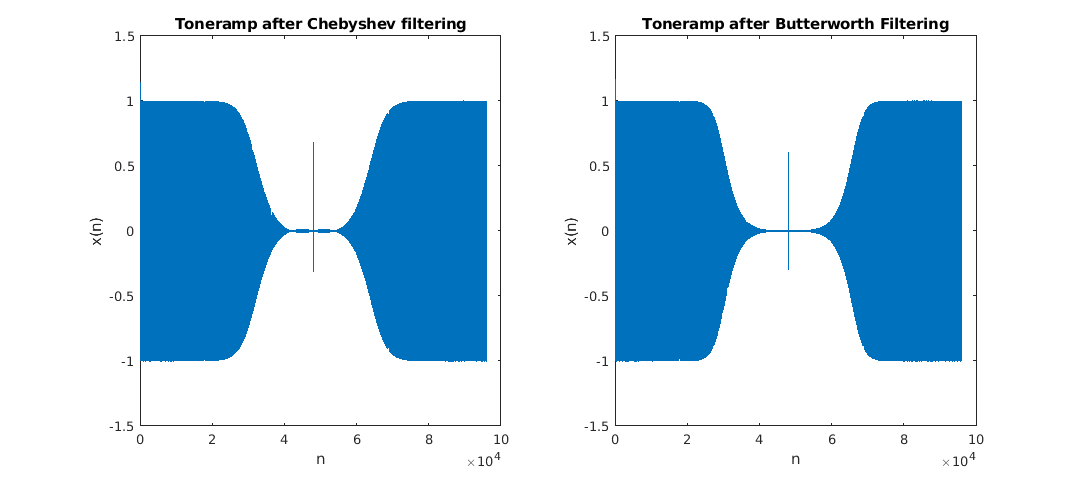

% Filtering the signal
chebyFilter = ChebyshevII;
toneramp_chebyFiltered = filter(chebyFilter, toneramp);

h = figure;
subplot(121)
plot(toneramp_chebyFiltered)
title('Toneramp after Chebyshev filtering')
xlabel('n')
ylabel('x(n)')
ylim([-1.5 1.50])

subplot(122)
plot(toneramp_butterFiltered)
title('Toneramp after Butterworth Filtering')
xlabel('n')
ylabel('x(n)')
set(h,'Units','normalized','Position',[0 0 1 0.25]);

*As you can see, the Chebyshev Type II produces some distortions in the middle of the signal where we want to filter and you can also hear them in the audio files. For that reason I chose butterworth over Chebyshev type II.*

*Now let's compare our Butterworth filter with previous designs in Problem 2.*

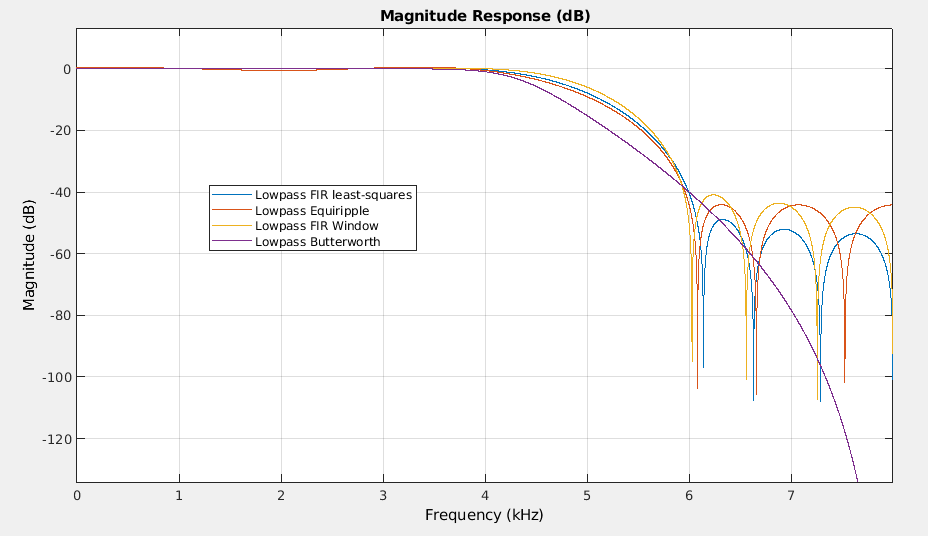

*Here's Butterworth advantages over the FIR filters:*

- *Butterworth has a narrower passband than the FIR filters.*

- *Butterworth's filter order is 6 while the lowest filter order in the FIR filters was 12.*

- *The design process of the butterworth filter was easier than the FIR filters.*

- *The Butterworth filter also gave us a better (cleaner) output than the FIR filters with no rippling effect.*

### Problem 4)

For the lowpass filter in Problem 2 you now need to increase the stopband attenuation to 70 dB. Explain which window methods can no longer be used and why.

*After experimenting with all the window funtions that's been introduced to us I realized all the windows can actually produce the stopband attenuatioin we want while meeting the other requirements from problem 2. But for some of these windows the filter order must be extremely high for it produce what we want.*

*Lets take a look at them:*

**Bartlet Window -  **$\mathbf{Minimum}\;\mathbf{Filter}\;\mathbf{Order}\;\approx 3000$  

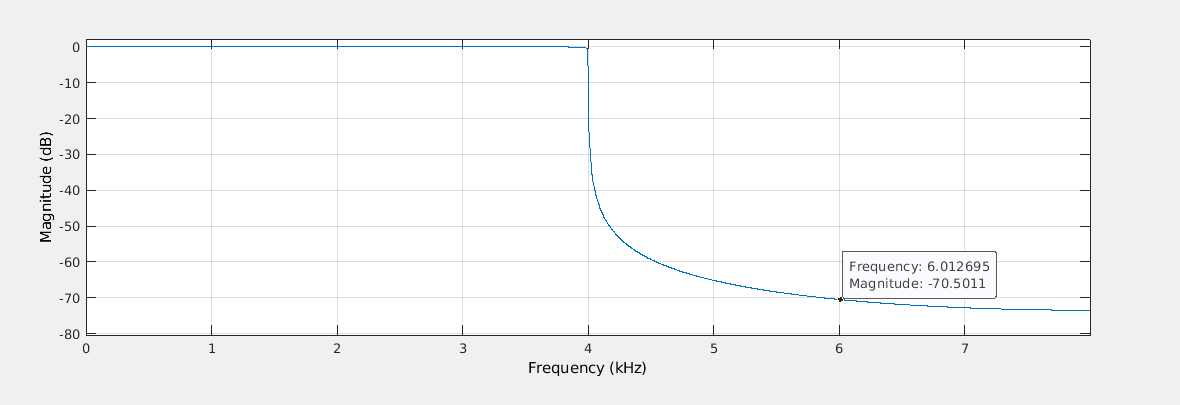

**Blackman Window -  **$\mathbf{Minimum}\;\mathbf{Filter}\;\mathbf{Order}\;\approx 50$  

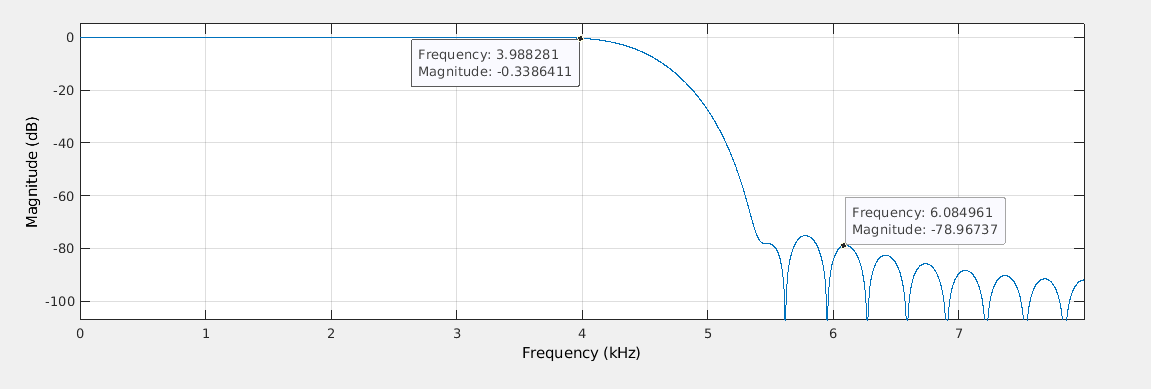

**Hamming Window -  **$\mathbf{Minimum}\;\mathbf{Filter}\;\mathbf{Order}\;\approx 250$  

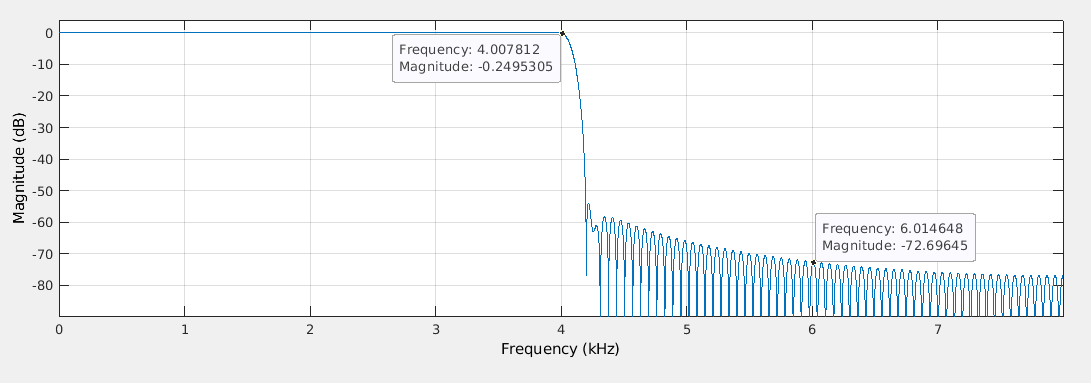

**Hann Window -  **$\mathbf{Minimum}\;\mathbf{Filter}\;\mathbf{Order}\;\approx 55$  

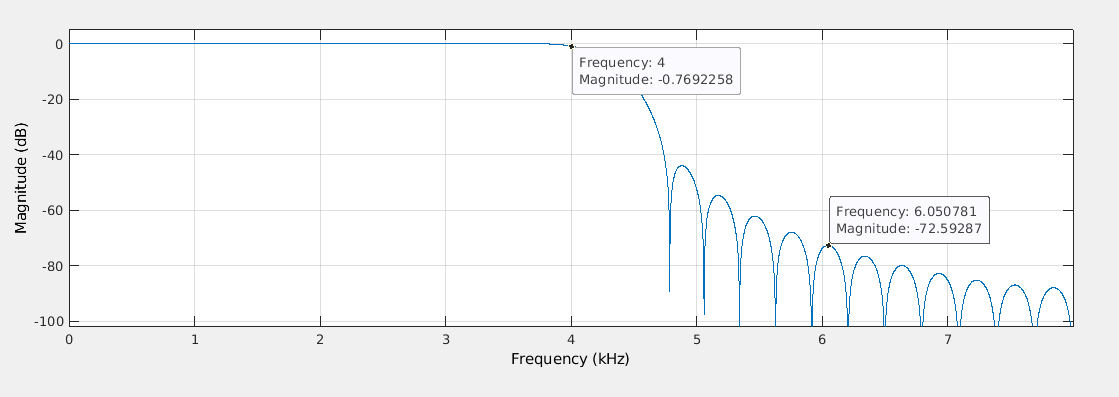

**Kaiser Window -  **$\mathbf{Minimum}\;\mathbf{Filter}\;\mathbf{Order}\;=37$

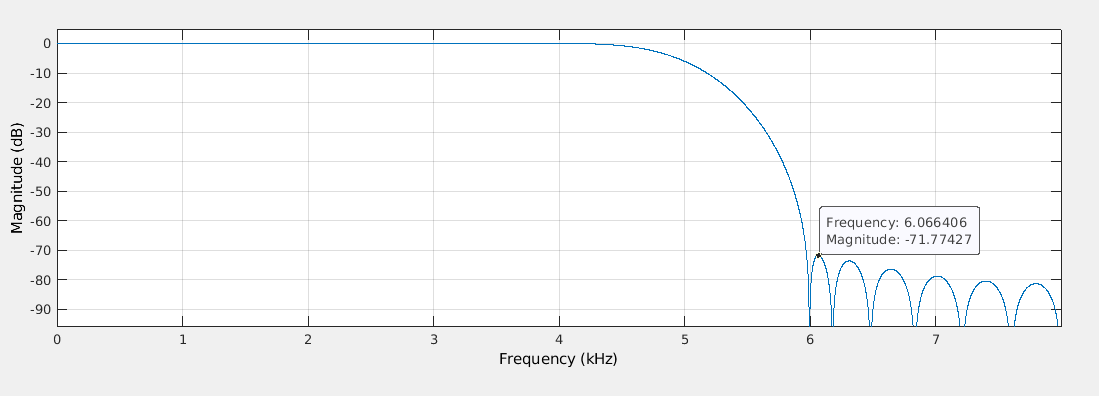

**Rectangular Window -  **$\mathbf{Minimum}\;\mathbf{Filter}\;\mathbf{Order}\approx 3000$

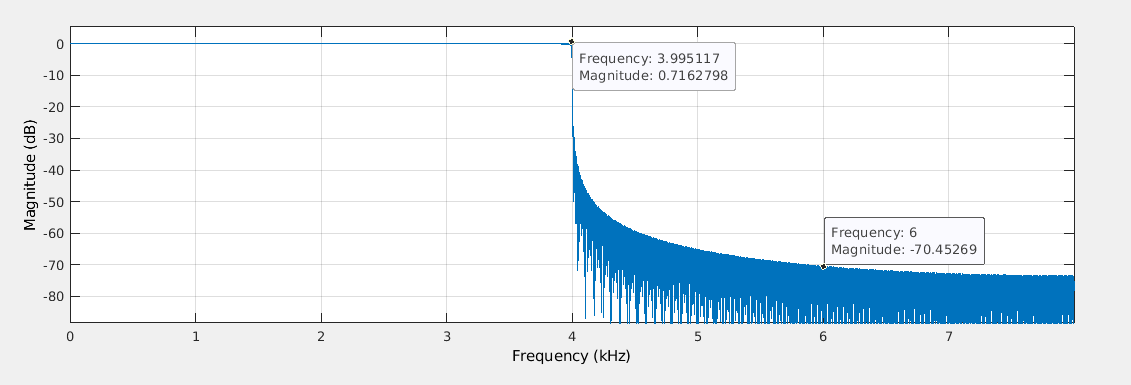

*As you can see, in the figures above, we are in fact able to produce the filter we want with all the window functions we were introduced to, however only the ****Kaiser, Blackman, ****and ****Hann ****could be practical with respect to their filter orders, Kaiser being the best one. *

*But looking at the ****Bartlett ****and ****Rectangular ****windows , we can say that those windows could not be practical and efficient to use as their filter order are extremely high which makes our computations very expensive. We might be able to use the ****Hamming ****window with respect to the hardware power of the computer. But again, in real world applications, choosing another window like ****Kaiser ****would make much more sense than ****Hamming ****as it would be significantly faster and more efficient.*

### Problem 7)

The following transfer function represents a second-order analog elliptic low-pass filter:


$$\frac{0\ldotp 0032s^2 +0\ldotp 0615}{s^2 +0\ldotp 2739s+0\ldotp 0690}$$


a) Plot the frequency response of this analog filter. Use a logarithmic scale in the frequency axis.

H = tf([0.0032 0 0.0615],[1 0.2739 0.069])

H =
 
   0.0032 s^2 + 0.0615
  ----------------------
  s^2 + 0.2739 s + 0.069
 
Continuous-time transfer function.



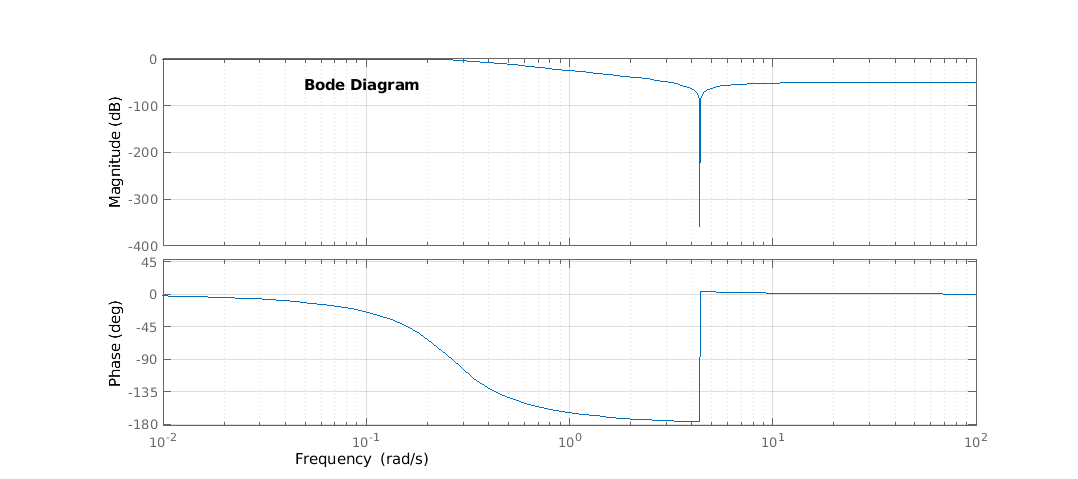

h = figure;
bode(H);
grid on
set(h,'Units','normalized','Position',[0 0 1 0.25]);

b) Show a pole-zero plot of this filter in the s-plane:

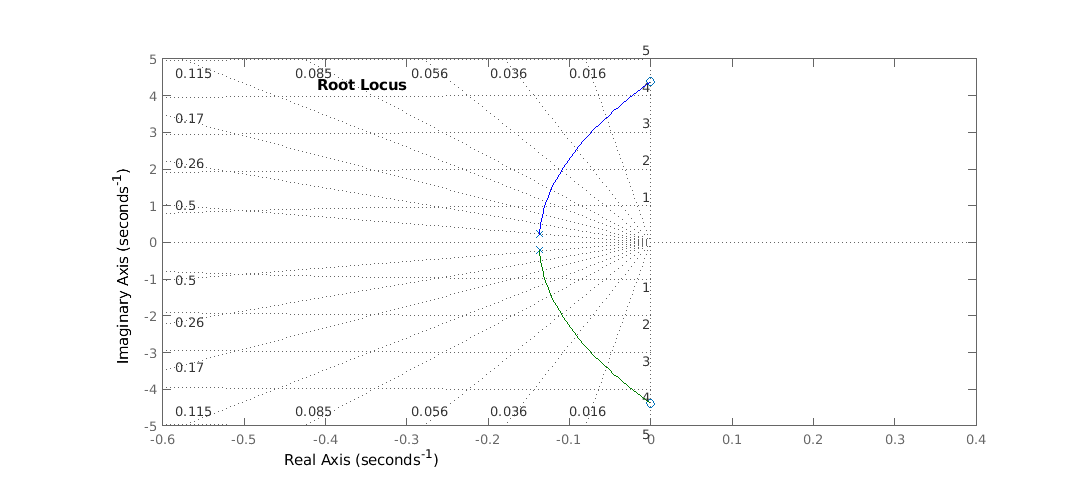

h = figure;
rlocus(H)
sgrid
set(h,'Units','normalized','Position',[0 0 1 0.25]);

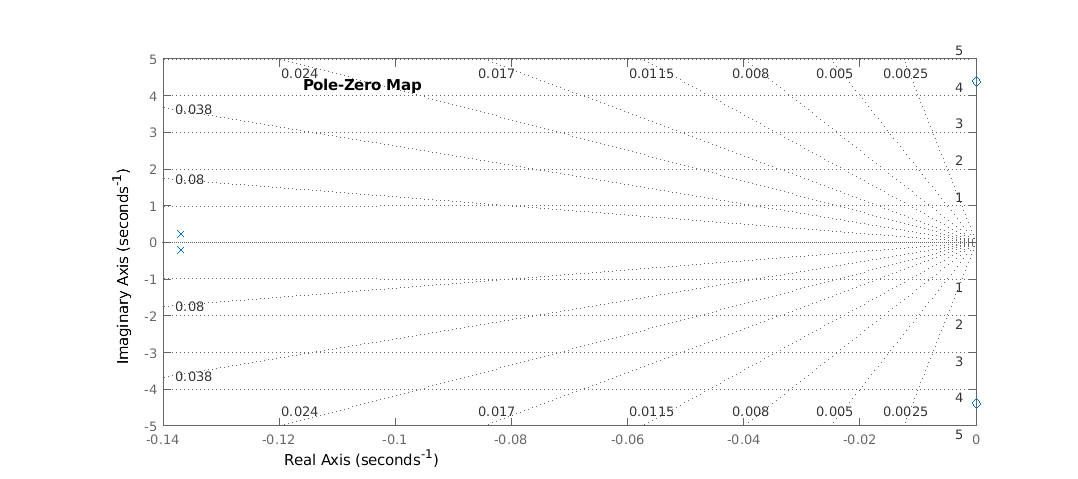

h = figure;
pzmap(H)
grid on
set(h,'Units','normalized','Position',[0 0 1 0.25]);

c) Transform this filter into a digital filter by using a bilinear transformation (by hand). Write the new transfer function H(z). Note that the design parameter T will remain in the equations.

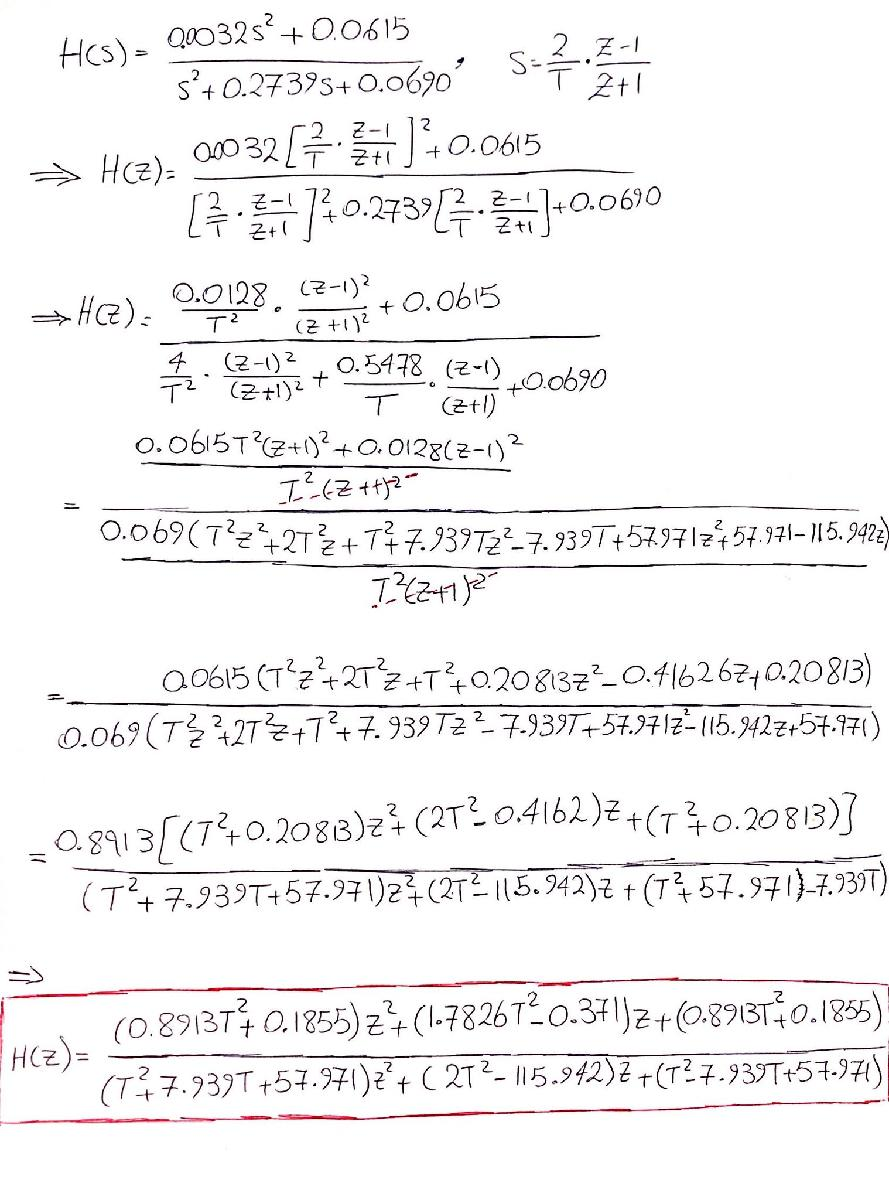

d) Plot the frequency response of the digital filter, assuming T=1.


$$H\left(z\right)=\frac{1\ldotp 0768{\;z}^2 +1\ldotp 4116\;z+1\ldotp 0768}{66\ldotp 91\;z^2 -113\ldotp 942+51\ldotp 032}$$



H2 = tf([1.0768 1.4116 1.0768],[66.91 -113.942 51.032],-1)

H2 =
 
  1.077 z^2 + 1.412 z + 1.077
  ---------------------------
  66.91 z^2 - 113.9 z + 51.03
 
Sample time: unspecified
Discrete-time transfer function.



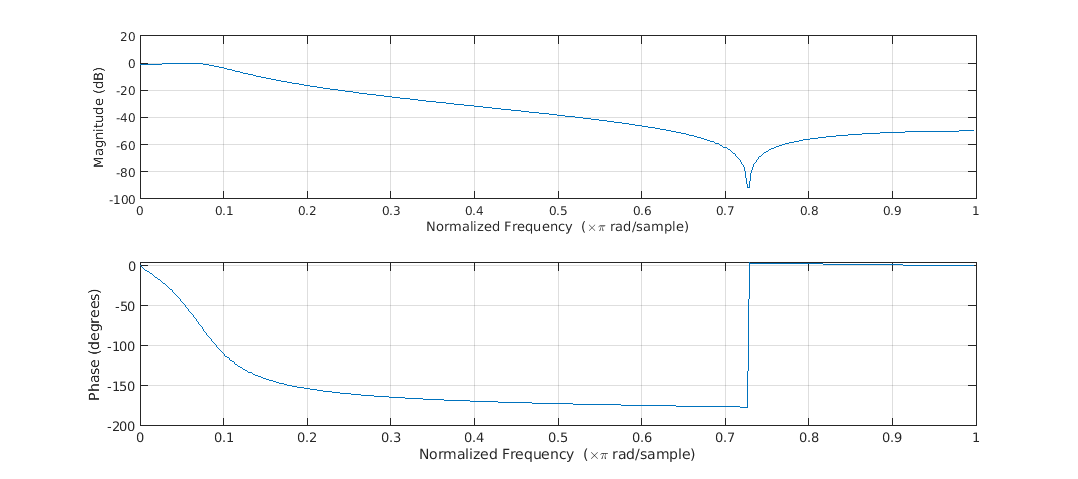

h = figure;
freqz(H2.Numerator{1}, H2.Denominator{1})
set(h,'Units','normalized','Position',[0 0 1 0.25]);

e) Show a pole-zero plot of the new filter in the z-plane, assuming T=1.

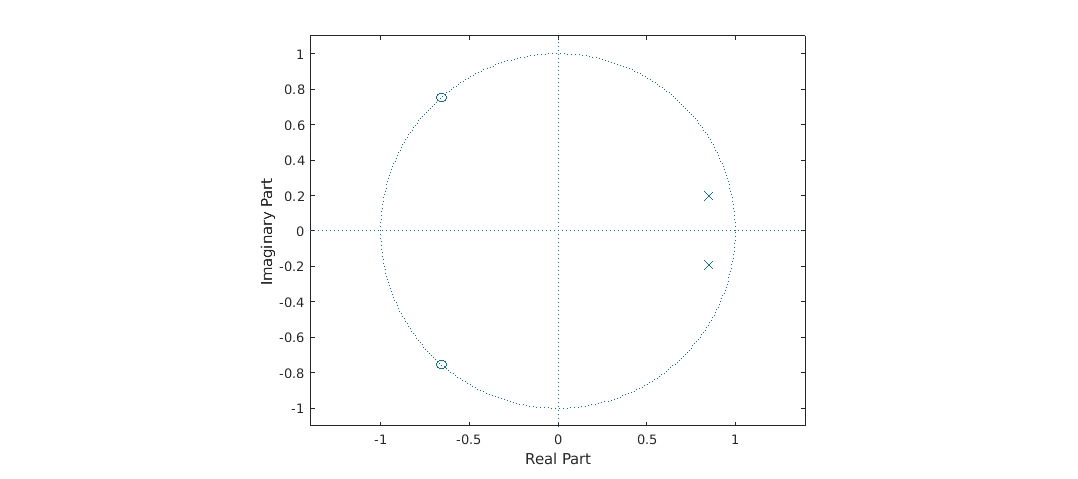

h = figure;
zplane(H2.Numerator{1}, H2.Denominator{1})
set(h,'Units','normalized','Position',[0 0 1 0.25]);

f) Comment between the similarities and differences observed between the behavior of the analog filter and the digital filter. 

- The order of the digital filter is the same as our original analog filter.

- The left-half s-plane is mapped into the unit circle on the z-plane. This means stability is preserved.

You can see how the frequency responses almost look identical. However, what we see as a discontinuity in our analog filter is no longer a discontinuity in our digital filter's frequency response.